%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_loewe.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'nature_ecoli';
standardize = '';

summaryTable = 1×11 table
      min      median      max      range     mean        std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    _______    _______    ______    _____    _______    _______    ________________    ____________    _______________    _______________    __________

    -1.4914    0.83761    1.6126    3.104    0.71121    0.56813           80                4                65                true           0.011395 


drugList = 11×1 cell array
    {0×0 char}
    {'CHL'   }
    {'CIP'   }
    {'ERY'   }
    {'FOX'   }
    {'FUS'   }
    {'PHL'   }
    {'RIF'   }
    {'SMX'   }
    {'TET'   }
    {'TMP'   }


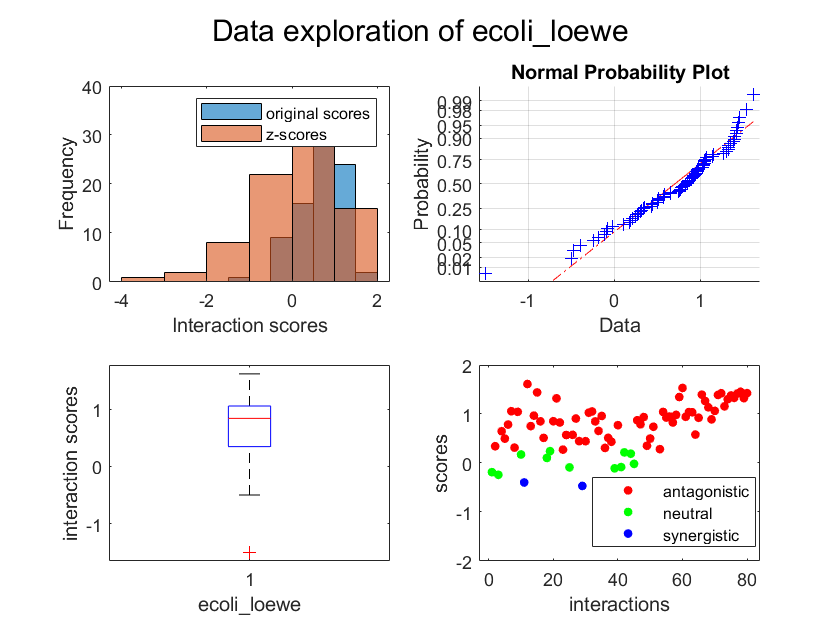

[summary,drugList] = dataExplore(testFile);

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,standardize);

Run 1
Elapsed time is 14.910767 seconds.
Run 2
Elapsed time is 13.986055 seconds.
Run 3
Elapsed time is 13.853098 seconds.
Run 4
Elapsed time is 12.379800 seconds.
Run 5
Elapsed time is 11.419531 seconds.


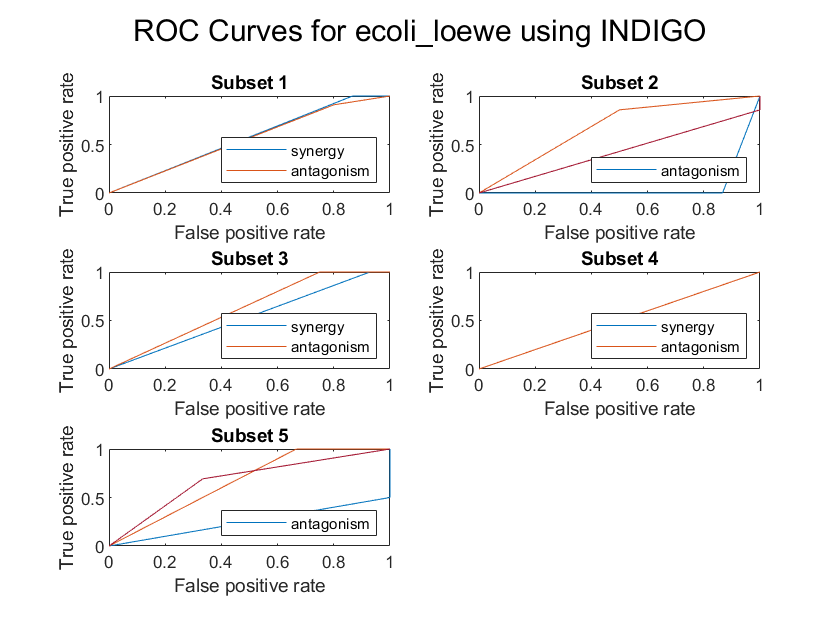

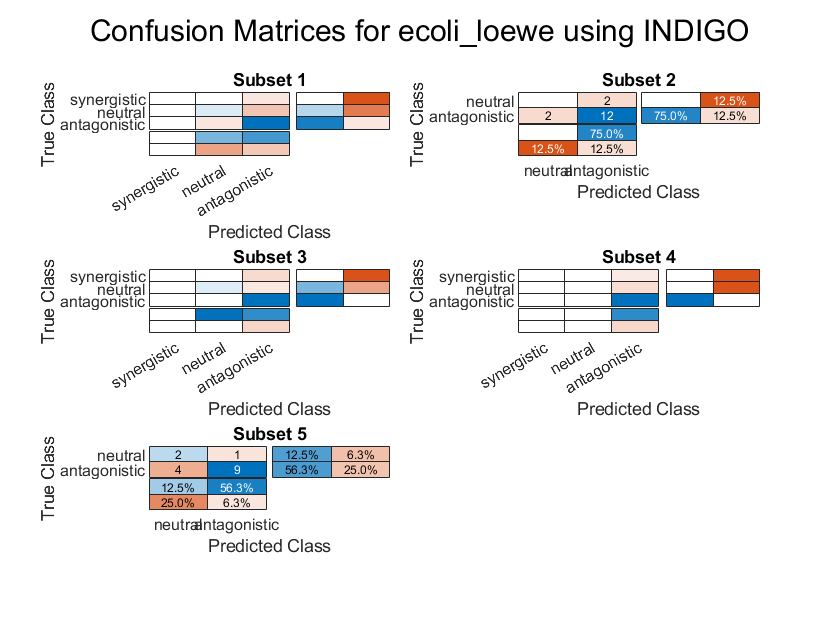

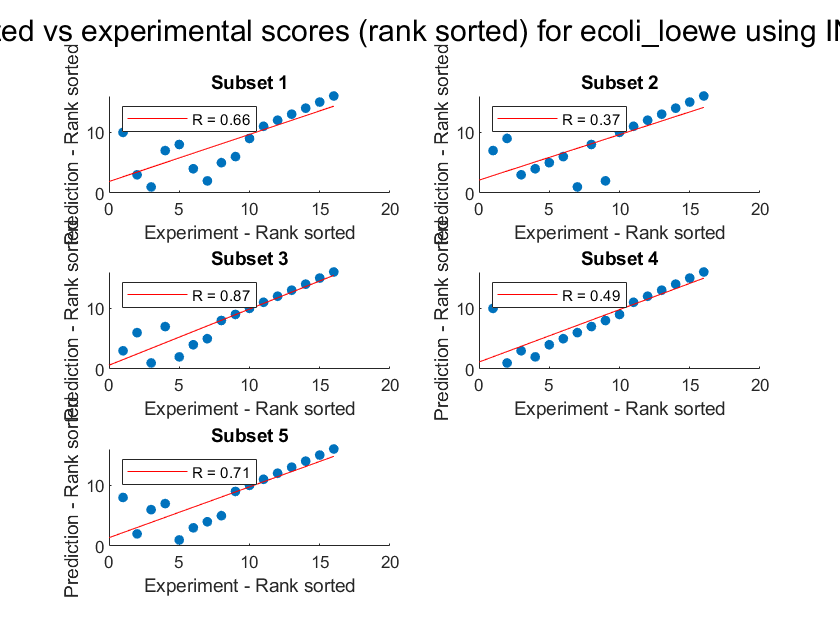

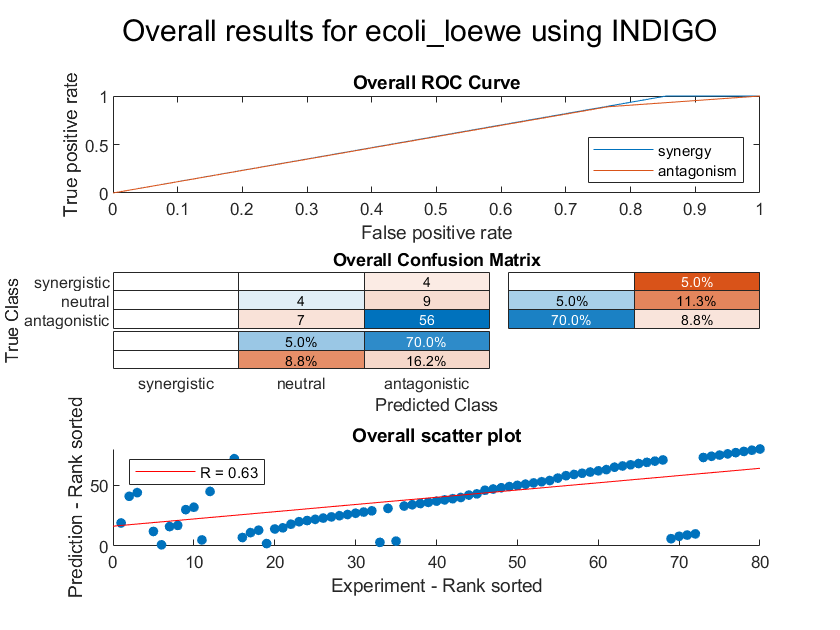

resultsTable = 5×13 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    __________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                      16
    R (rank)                        0.62
    P value                     0.045287
    Accuracy                        0.75
    Absolute error                   0.3
    Precision (synergy)              NaN
    Recall (synergy)                 NaN
    Precision (antagonism)       0.81679
    Recall (antagonism)          0.89171
    Mean Guess Error               -0.75
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)              NaN
    AUC - ROC (antagonism)       0.55752


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                        80
    R (rank)                        0.6332
    P value                     2.9272e-10
    Accuracy                          0.75
    Absolute error                     0.3
    Precision (synergy)                NaN
    Recall (synergy)                     0
    Precision (antagonism)         0.81159
    Recall (antagonism)            0.88889
    Mean Guess Error                 -0.75
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.57237
    AUC - ROC (antagonism)         0.56209


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_loewe.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'nature_ecoli';
standardize = 'standardized';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 9.747310 seconds.
Run 2
Elapsed time is 9.903706 seconds.
Run 3
Elapsed time is 10.195249 seconds.
Run 4
Elapsed time is 10.692759 seconds.
Run 5
Elapsed time is 10.257196 seconds.


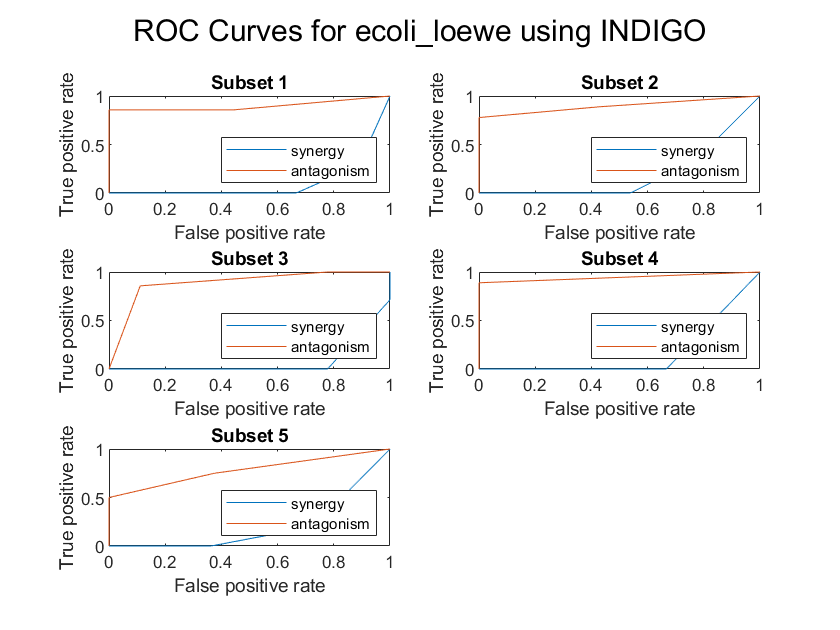

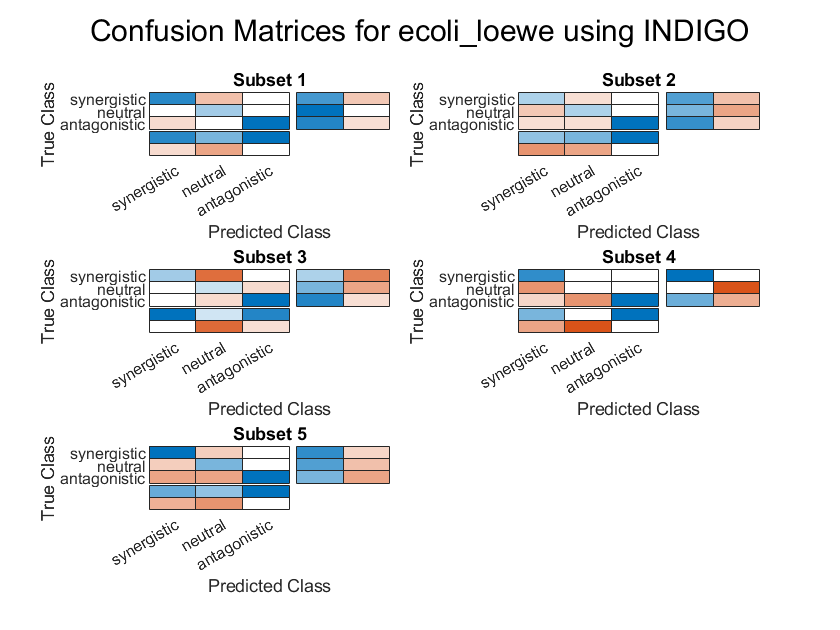

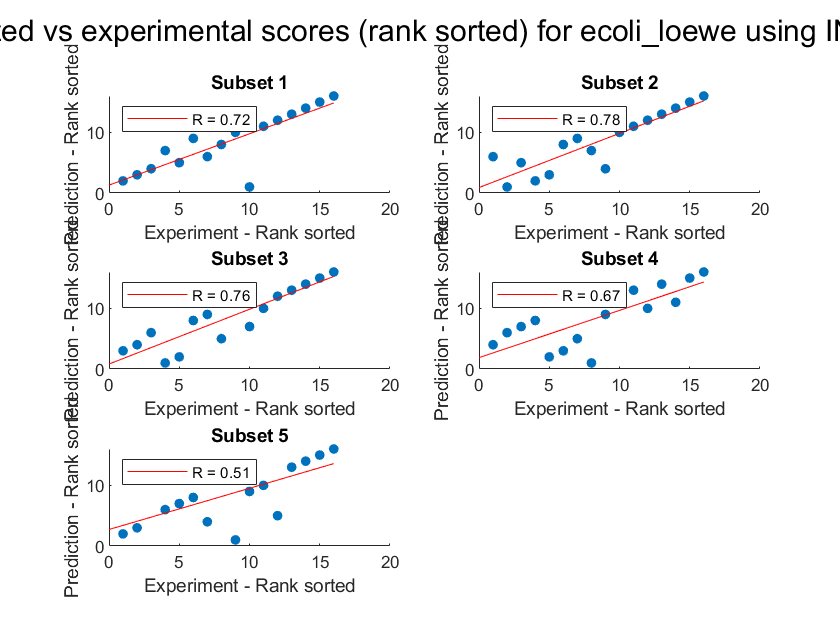

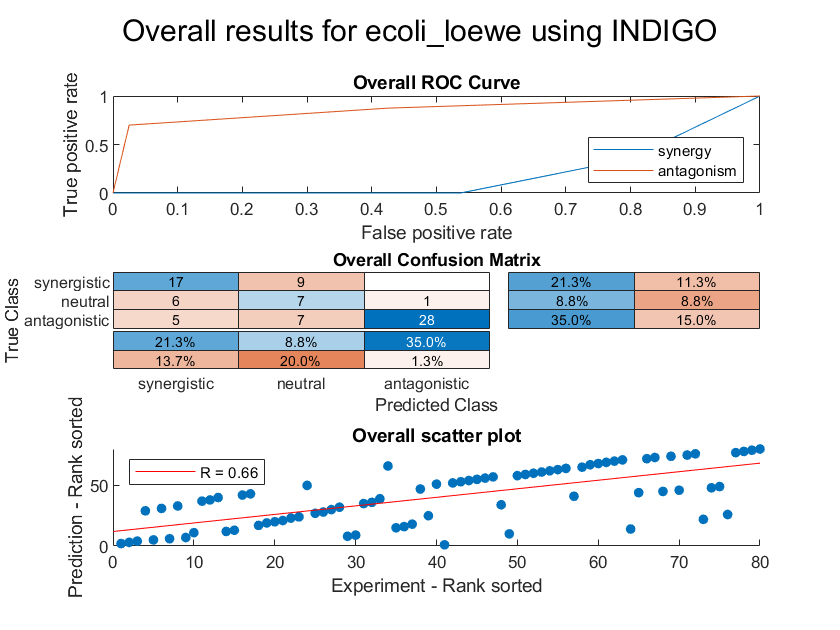

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                      16
    R (rank)                     0.68882
    P value                     0.011119
    Accuracy                        0.65
    Absolute error                0.4125
    Precision (synergy)          0.66095
    Recall (synergy)             0.69333
    Precision (antagonism)       0.97143
    Recall (antagonism)          0.70952
    Mean Guess Error               -0.65
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)           0.1483
    AUC - ROC (antagonism)       0.88165


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                        80
    R (rank)                          0.66
    P value                     2.7537e-11
    Accuracy                          0.65
    Absolute error                  0.4125
    Precision (synergy)            0.60714
    Recall (synergy)               0.65385
    Precision (antagonism)         0.96552
    Recall (antagonism)                0.7
    Mean Guess Error                 -0.65
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.18198
    AUC - ROC (antagonism)         0.86281


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_loewe.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_bw25113.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 31.202632 seconds.
Run 2
Elapsed time is 32.521555 seconds.
Run 3
Elapsed time is 32.131278 seconds.
Run 4
Elapsed time is 32.184523 seconds.
Run 5
Elapsed time is 31.984234 seconds.


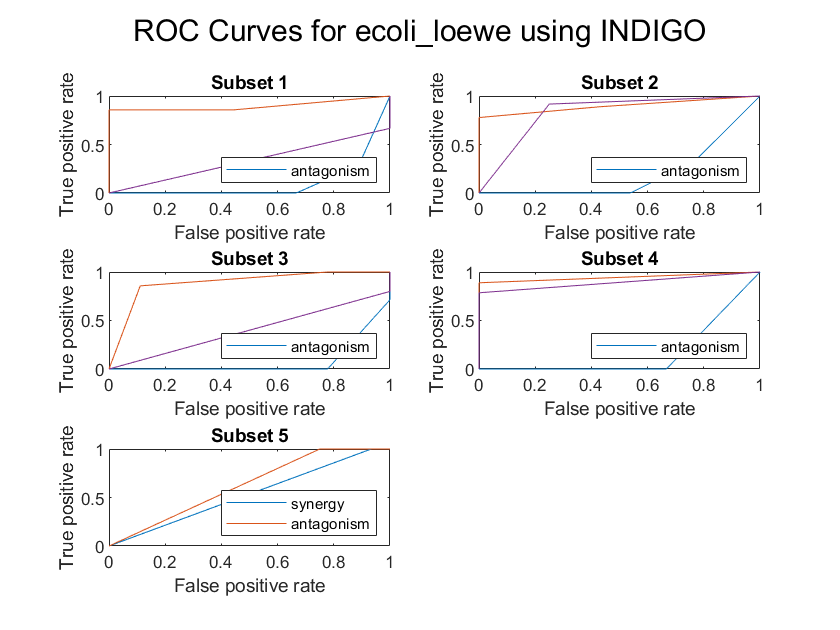

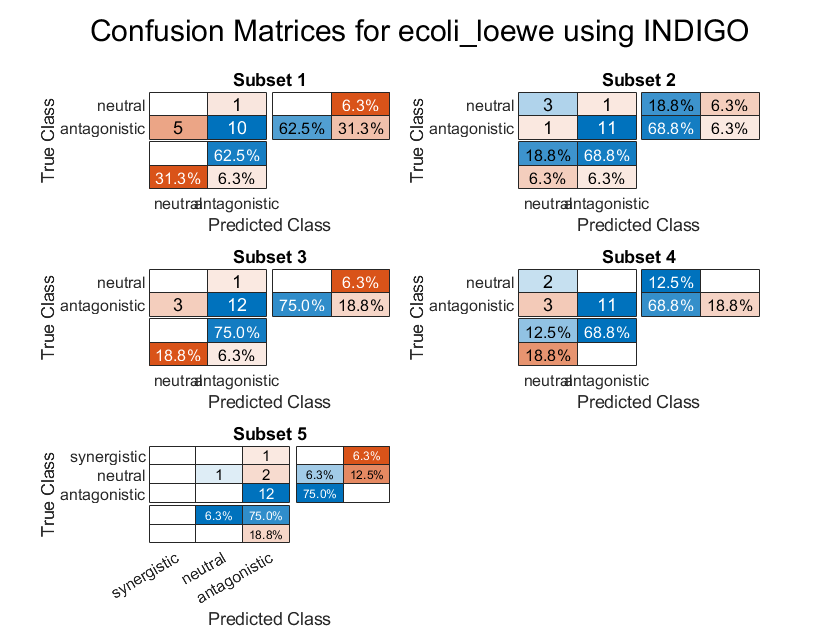

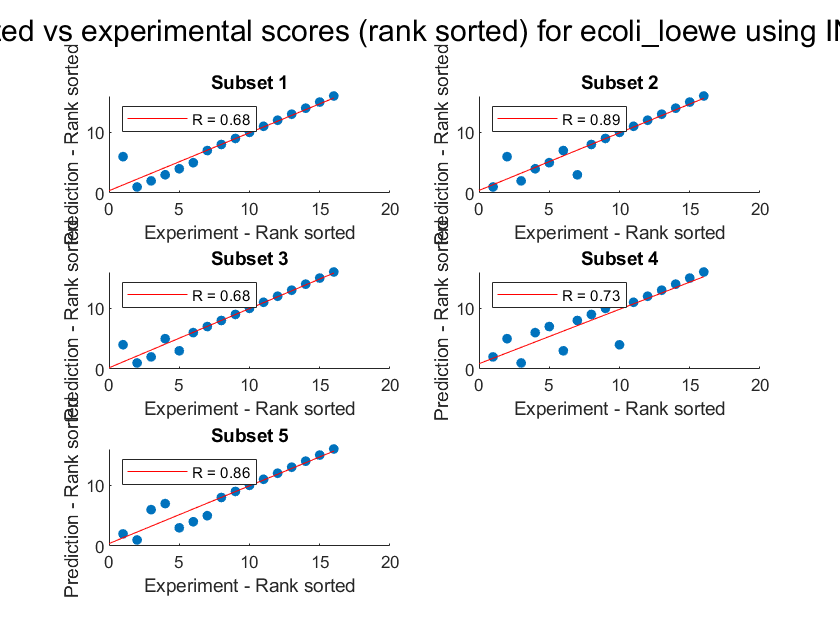

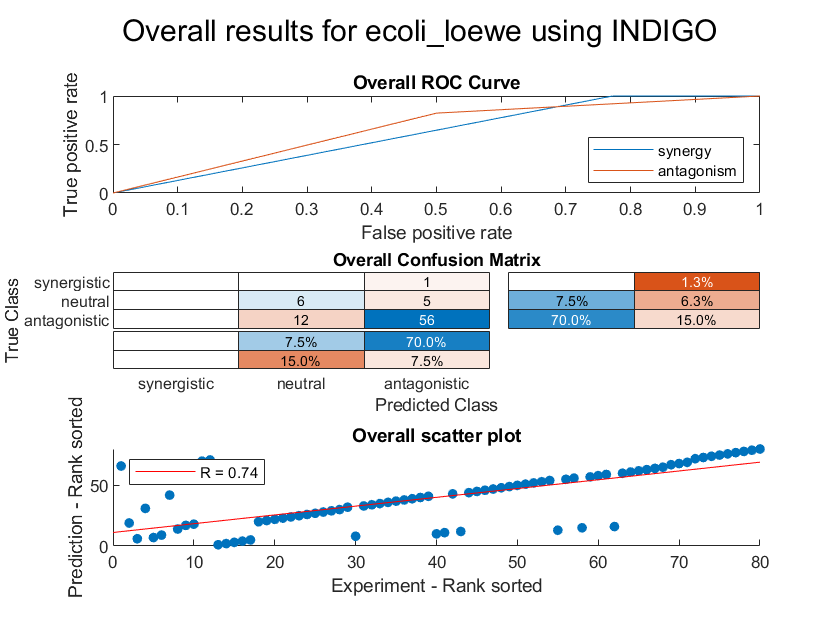

resultsTable = 5×13 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    __________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                      16
    R (rank)                     0.76588
    P value                     0.002371
    Accuracy                       0.775
    Absolute error                0.2375
    Precision (synergy)              NaN
    Recall (synergy)                 NaN
    Precision (antagonism)       0.90977
    Recall (antagonism)          0.83381
    Mean Guess Error              -0.775
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)              NaN
    AUC - ROC (antagonism)        0.6169


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                        80
    R (rank)                       0.74099
    P value                     3.8951e-15
    Accuracy                         0.775
    Absolute error                  0.2375
    Precision (synergy)                NaN
    Recall (synergy)                     0
    Precision (antagonism)         0.90323
    Recall (antagonism)            0.82353
    Mean Guess Error                -0.775
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.61392
    AUC - ROC (antagonism)         0.66176


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_loewe.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_iAi1.xlsx';
trainingOrthology = 'ecoli_iAi1_orthologs.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,trainingOrthology,standardize);

Run 1
Elapsed time is 30.298665 seconds.
Run 2
Elapsed time is 34.697659 seconds.
Run 3
Elapsed time is 32.518293 seconds.
Run 4
Elapsed time is 30.853131 seconds.
Run 5
Elapsed time is 31.607921 seconds.


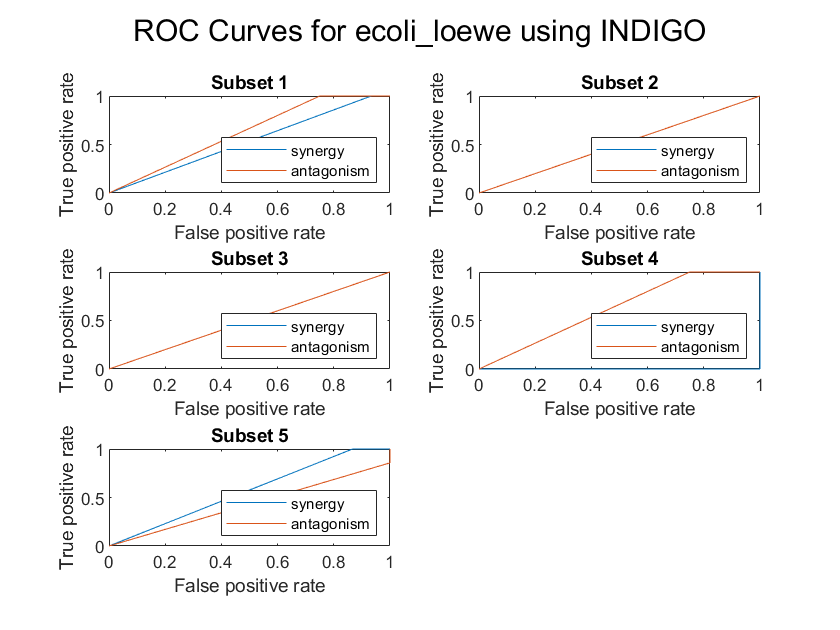

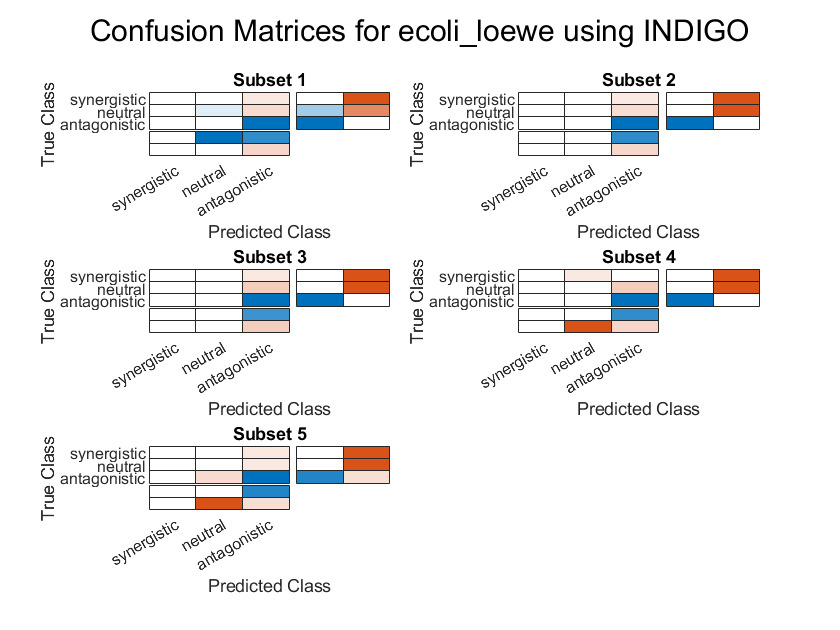

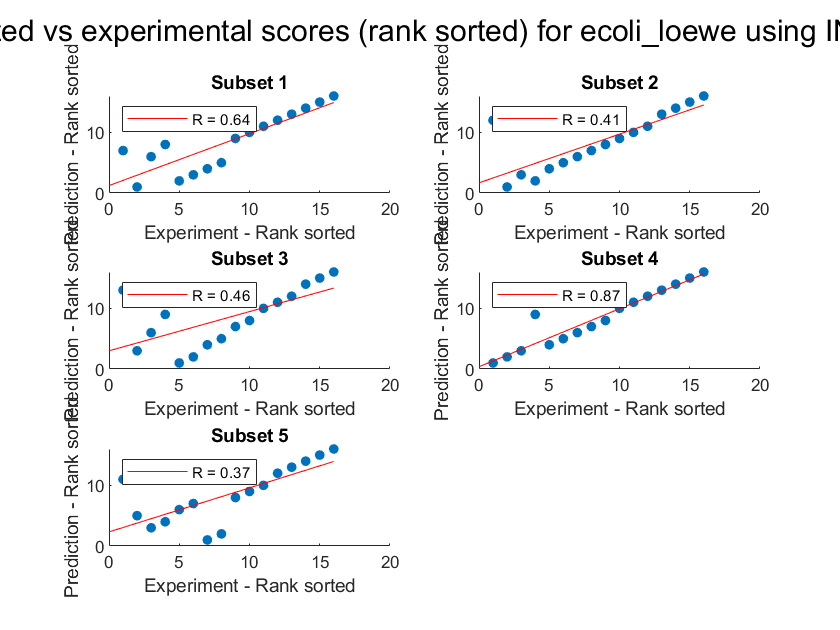

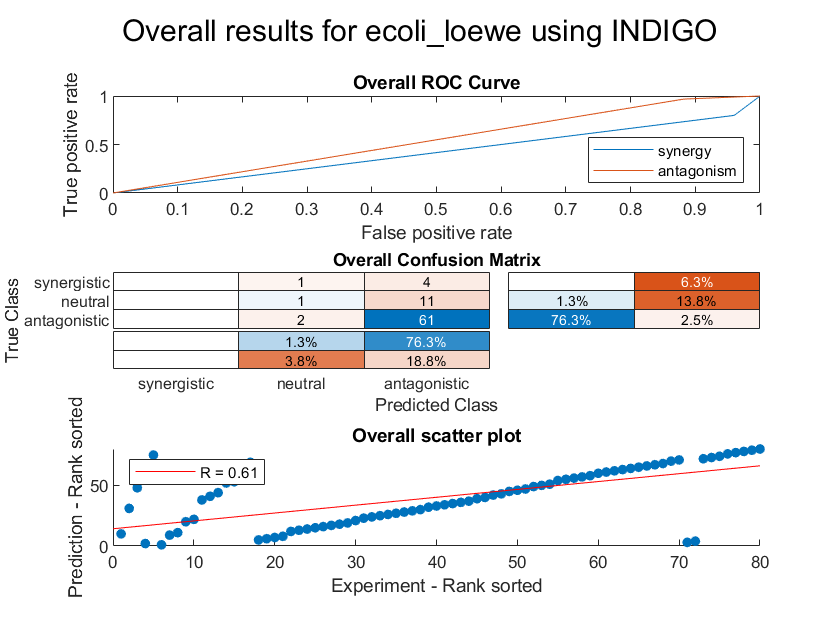

resultsTable = 5×13 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    __________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                      16
    R (rank)                     0.55118
    P value                     0.072104
    Accuracy                       0.775
    Absolute error                 0.275
    Precision (synergy)              NaN
    Recall (synergy)                   0
    Precision (antagonism)       0.80393
    Recall (antagonism)          0.97143
    Mean Guess Error              -0.775
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)             0.42
    AUC - ROC (antagonism)       0.53571


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                        80
    R (rank)                       0.60906
    P value                     2.0396e-09
    Accuracy                         0.775
    Absolute error                   0.275
    Precision (synergy)                NaN
    Recall (synergy)                     0
    Precision (antagonism)         0.80263
    Recall (antagonism)            0.96825
    Mean Guess Error                -0.775
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)               0.42
    AUC - ROC (antagonism)         0.54295


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))